LADRC 参数设定

% 一些必要参数设定
wc=3; wo=5*wc;
b1=30.3;  % 如果想要反应快速的话, 就用 b1=0.2
b2=0.103;

ADRC 

速度控制器参数


% Ts
para_u.h=0.01; % 0.001 效果最好。 0.01 有毛刺，但是还是可以跟踪。

% TD para
para_u.r0=0.1;
para_u.h0=0.01;
% ESO para
para_u.beta01=1;
para_u.beta02=3;
para_u.beta03=10;
para_u.b0=0.1; 
% WARNING 
% b0 论文原数值 0.01 输出不收敛(有高频分量), 控制器输出高频大幅度振荡
% 这里改成 0.1 收敛

% NLSEF para
para_u.beta1=100;
para_u.beta2=4.5;
para_u.a1=0.75;
para_u.a2=1.5;


航向控制器参数

% Ts
para_yaw.h=0.01;
% TD para
para_yaw.r0=2; % 2
para_yaw.h0=0.01;
% ESO para
para_yaw.beta01=1;
para_yaw.beta02=2;
para_yaw.beta03=10;
para_yaw.b0=0.02;
% NLSEF para
para_yaw.beta1=10;
para_yaw.beta2=13;
para_yaw.a1=0.75;
para_yaw.a2=1.5;


读取路径

path = csvread('../path1.csv');

usv 初始条件 (初始位置放在起点)

init_x=path(1,1);
init_y=path(1,2);
init_psi=0;

生成路径

figure;hold;

已锁定最新绘图


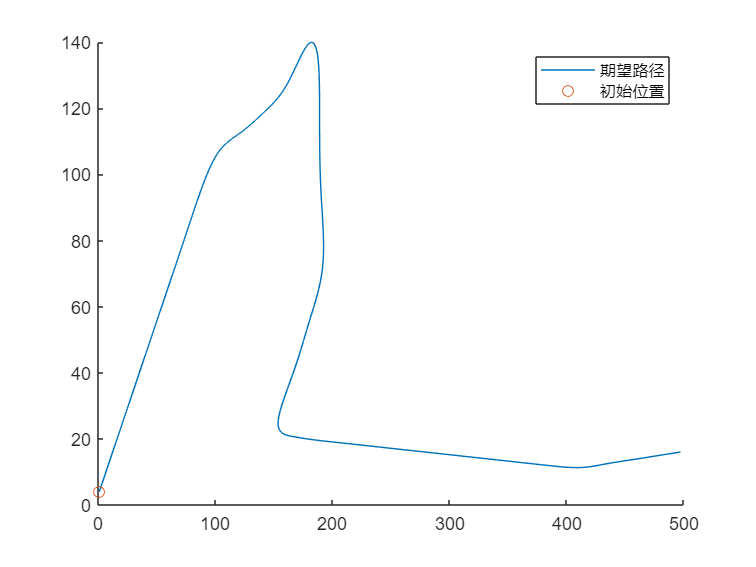

plot(path(:,1),path(:,2));
scatter(init_x,init_y);
legend("期望路径","初始位置");

LADRC (deprecated)

% out = sim("LADRC_Control.slx");
% 
% plot(out.x.Data,out.y.Data); 
% width=40;  xlim([-width,width]); ylim([-width,width]);
% title("X-Y")

%Simulink.sdi.view;


adrc 仿真

out = sim("ADRC_Control.slx");

仿真结果

figure; hold;

已锁定最新绘图


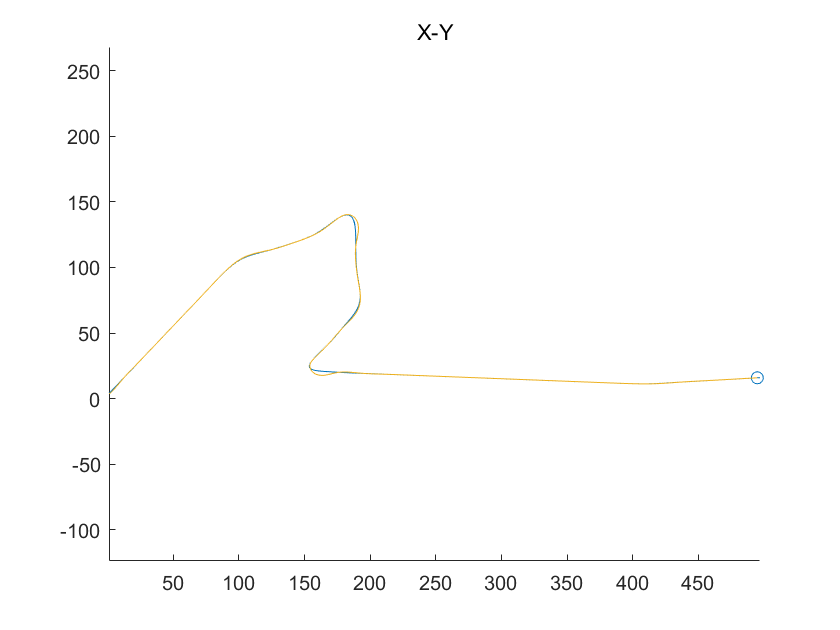


%scatter(path(:,1),path(:,2),5)
plot(path(:,1),path(:,2))
plot(path(1:2,1),path(1:2,2),"red")
axis equal;
title("X-Y");

x=out.xy.Data(1,1:100:end);
y=out.xy.Data(2,1:100:end);
comet(x,y)

仿真数据导出, 供 Unity 使用 . 

原始数据实际上是等步长的仿真. 0.001s --> 等100间隔采样, 获得 0.1s 的数据

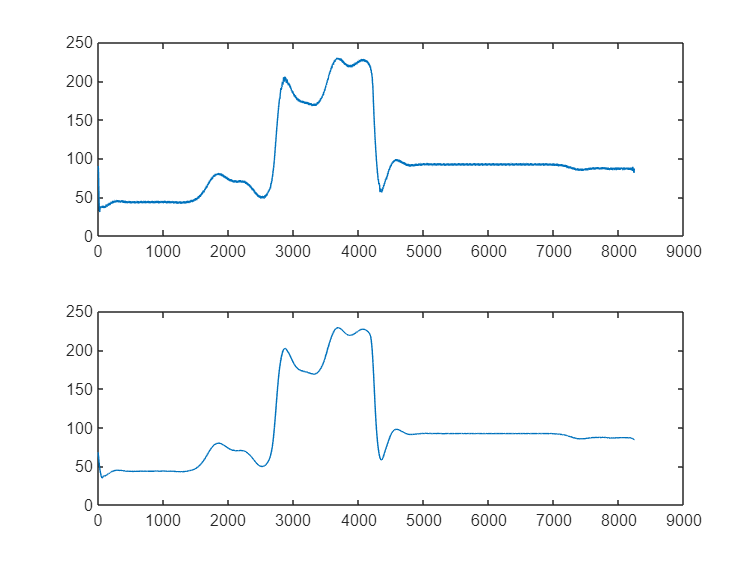

x=transpose(out.xy.Data(1,1:100:end));
y=transpose(out.xy.Data(2,1:100:end));
psi=out.psi.Data(1:100:end);

% 转化为 unity 需要的角度值
psi_angle=0.5*pi-psi;
% while(max(abs(psi_angle))>pi) % -pi - pi 区间
%     psi_angle(psi_angle>2*pi)=psi_angle(psi_angle>2*pi)-2*pi;
%     psi_angle(psi_angle<-2*pi)=psi_angle(psi_angle<-2*pi)+2*pi;
% end
psi_angle=psi_angle/pi*180;
smoothed_psi_angle=smoothdata(psi_angle,'loess',"SmoothingFactor",0.01); % 平滑处理 (有波动, 观感不太好) 0.2, 0.01

figure;
subplot(2,1,1);plot(psi_angle);
subplot(2,1,2);plot(smoothed_psi_angle);


data=[x,y,smoothed_psi_angle];
dlmwrite('../final_path1.csv',data,'precision','%.5f'); % 输出 csv, 保留5位小数
